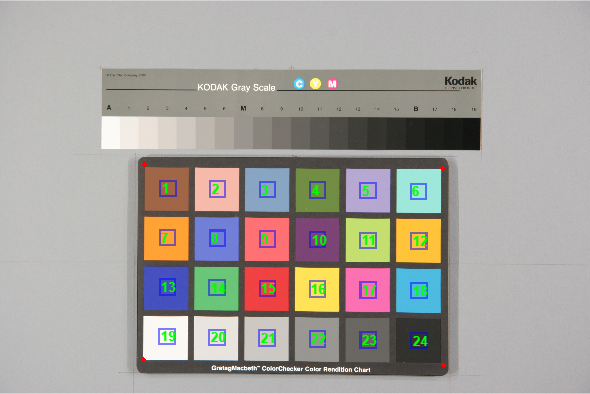

%Input người dùng cần nhập
input_db = 10;
input_luma_target = 95;

A = imread('Stepchart-Linear_EV+1.png');
chart = colorChecker(A,"Sensitivity",0.7);
% Đọc input và detect chart
displayChart(chart);

T = measureColor(chart);
% Tính giá trị luminance cho từng patch
luminanceValues = 0.2126 * T.Measured_R + 0.7152 * T.Measured_G + 0.0722 * T.Measured_B;

% Hiển thị tên và giá trị luminance của từng patch
patchNames = T.Color;
disp('Luminance của từng patch:');

Luminance của từng patch:


for i = 19:length(luminanceValues)
    %fprintf('Patch %s Luminance = %.2f\n', char(patchNames(i)), luminanceValues(i));
    fprintf('Patch %i có độ sáng = %.2f\n', i, luminanceValues(i));
end

Patch 19 có độ sáng = 248.00
Patch 20 có độ sáng = 229.00
Patch 21 có độ sáng = 201.00
Patch 22 có độ sáng = 152.00
Patch 23 có độ sáng = 103.00
Patch 24 có độ sáng = 50.00





% Giá trị imatest document cung cấp
exposure_ideal = [-0.23, -0.44, -0.7, -1.05];

% Lấy giá trị luminance của các patch 20, 21, 22, 23
values_double = double(luminanceValues(20:23));

% Tính log10
exposure_measure = log10(values_double / 255);

% Hiển thị kết quả
%disp(exposure_measure);




% Hàm để lấy gamma dựa trên input_db
function gamma_values = get_gamma(input_db)
    % Dữ liệu gamma tính theo công thức imatest
    out_door_gamma_2_2 = [195, 157, 119, 83];
    in_door_gamma_1_8 = [184, 141, 100, 65];
    low_light_gamma_1_4 = [167, 119, 77, 44];
    
    % Ngưỡng dB
    threshold_outdoor = [0, 6];
    threshold_indoor = [7, 18];
    threshold_lowlight = [19, 30];
    
    % Kiểm tra ngưỡng và trả về gamma tương ứng
    if input_db >= threshold_outdoor(1) && input_db <= threshold_outdoor(2)
        gamma_values = out_door_gamma_2_2;
    elseif input_db >= threshold_indoor(1) && input_db <= threshold_indoor(2)
        gamma_values = in_door_gamma_1_8;
    elseif input_db >= threshold_lowlight(1) && input_db <= threshold_lowlight(2)
        gamma_values = low_light_gamma_1_4;
    else
        gamma_values = []; % Nếu input_db ngoài khoảng từ 0 đến 30 dB
        disp('Input dB nằm ngoài ngưỡng đã đặt.');
    end
end


% Sử dụng polyfit để tìm hệ số của đường thẳng (bậc 1)
p = polyfit(exposure_ideal, exposure_measure, 1);

% Tạo giá trị x để vẽ đồ thị
x_fit = linspace(min(exposure_ideal), max(exposure_ideal), 100);
y_fit = polyval(p, x_fit);


% Hiển thị hệ số của đường thẳng
a = p(1); % Hệ số a (độ dốc)
b = p(2); % Hệ số b (hằng số)
disp(['Độ dốc của Gamma Curve = ',num2str(a)]);

Độ dốc của Gamma Curve = 0.43206


% disp(['Giá trị Exposure Error = ',num2str(b)]);
% Tính giá trị gamma
gamma_value = 1 / a;
% Hiển thị giá trị gamma
disp(['Gamma Curve = ', num2str(gamma_value)]);

Gamma Curve = 2.3145



% % Vẽ đồ thị
% figure;
% scatter(exposure_ideal, exposure_measure, 'filled', 'r'); % Điểm đo
% hold on;
% plot(x_fit, y_fit, 'b-', 'LineWidth', 2); % Đường thẳng từ hồi quy tuyến tính
% plot(exposure_ideal, exposure_measure, 'r--', 'LineWidth', 1.5); % Đường nối 4 điểm, màu đỏ nét đứt
% xlabel('Exposure Ideal');
% ylabel('Exposure Measure');
% title('Linear Fit through 4 Points');
% legend('Measured Values', 'Linear Fit', 'Direct Connection');
% grid on;
% hold off;



% Đặt gamma lý tưởng
gamma_2_2 = 2.2;

% Pixel level từ gamma 2.2 (ví dụ giả định hoặc từ mô hình)
gamma_2_2_pixel_levels = [236; 195; 157; 119; 83; 52];  % 6x1 column vector

% Chuyển sang mức reflectance linear
linear_levels = (gamma_2_2_pixel_levels / 255) .^ gamma_2_2;

% Áp dụng gamma đo được từ ảnh để mô phỏng pixel output (chỉ để so sánh)
gamma_ideal_pixel_levels = round((linear_levels .^ (1 / gamma_value)) * 255);

disp('Mức pixel lý tưởng theo gamma đo được:');

Mức pixel lý tưởng theo gamma đo được:


disp(gamma_ideal_pixel_levels);

   237
   198
   161
   124
    88
    56




% Log của pixel lý tưởng (nếu muốn kiểm tra)
ideal_gamma_calculate = log10(gamma_ideal_pixel_levels / 255);
disp('Log10(pixel/255) của pixel lý tưởng:');

Log10(pixel/255) của pixel lý tưởng:


disp(ideal_gamma_calculate);

   -0.0318
   -0.1099
   -0.1997
   -0.3131
   -0.4621
   -0.6584




% === VẼ BIỂU ĐỒ: Pixel Output vs Linear Reflectance Input ===
imatest_reflect = [-0.05 ,-0.23, -0.44, -0.7, -1.05 , -1.5]

imatest_reflect =    -0.0500   -0.2300   -0.4400   -0.7000   -1.0500   -1.5000


% Reflectance tuyến tính của patch 19–24
reflectance_input = 10.^imatest_reflect;  % Trục X
pixel_output = double(luminanceValues(19:24)');
% Fit tuyến tính và bậc 2 từ dữ liệu đo pixel
fit_1st = polyfit(reflectance_input, gamma_ideal_pixel_levels, 2);  % đường xanh
fit_2nd = polyfit(reflectance_input, pixel_output, 2);  % đường cam

% Tạo x mịn để vẽ
x_range = linspace(min(reflectance_input), max(reflectance_input), 100);

% Tính các đường cong
y_fit1 = polyval(fit_1st, x_range);              % tuyến tính
y_fit2 = polyval(fit_2nd, x_range);              % bậc 2
y_gamma22 = 255 * x_range.^(1 / gamma_2_2);      % gamma 2.2 (chuẩn lý tưởng)



% ==== TÍNH EXPOSURE ERROR (F-STOPS) THEO PATCH 20–23 ====

% Lấy reflectance của patch 20–23 (tức 2–5)
ref_input_patch = reflectance_input(2:5);  % đầu vào reflectance tuyến tính

% Giá trị pixel reference từ đường fit (fit_1st: đường xanh)
fitted_reference_patch = polyval(fit_1st, ref_input_patch);  % giá trị lý tưởng

% Tính log10 của measured và reference
log_measured = log10(values_double');
log_reference = log10(fitted_reference_patch);

% Δ(log exposure) cho từng patch
delta_log_exposure = (log_measured - log_reference) / gamma_value;

% Trung bình sai số log exposure
mean_delta = mean(delta_log_exposure);

% Tính Exposure Error (f-stops)
exposure_error_fstop = 3.32 * mean_delta;

% In kết quả
fprintf('\nExposure Error (f-stops) từ patch 20–23 so với đường fit xanh = %.4f f-stops\n', exposure_error_fstop);


Exposure Error (f-stops) từ patch 20–23 so với đường fit xanh = 0.1260 f-stops


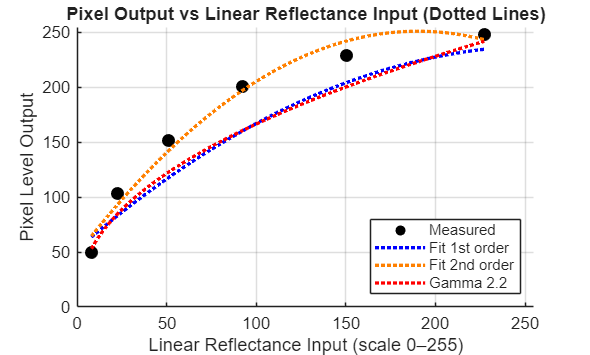


% Vẽ biểu đồ với giới hạn trục và các đường dotted
figure;
hold on;

scatter(255 * reflectance_input, pixel_output, 60, 'k', 'filled');  % Dữ liệu đo

plot(255 * x_range, y_fit1, ':', 'Color', 'b', 'LineWidth', 2);           % Xanh dương - tuyến tính
plot(255 * x_range, y_fit2, ':', 'Color', [1, 0.5, 0], 'LineWidth', 2);   % Cam - bậc 2
plot(255 * x_range, y_gamma22, ':', 'Color', 'r', 'LineWidth', 2);       % Đỏ - gamma 2.2

xlabel('Linear Reflectance Input (scale 0–255)');
ylabel('Pixel Level Output');
title('Pixel Output vs Linear Reflectance Input (Dotted Lines)');
legend('Measured', 'Fit 1st order', 'Fit 2nd order', 'Gamma 2.2', 'Location', 'southeast');

xlim([0 255]);
ylim([0 255]);
grid on;


% Đọc dữ liệu từ file
data = load('current_gamma_curve.txt');
% Hiển thị dữ liệu lên Command Window
%disp(data);

% Nếu bạn muốn vẽ biểu đồ đường cong gamma
%figure;
%plot(data, '-o');
%title('Gamma Curve');
%xlabel('Index');
%ylabel('Value');
%grid on;

target_gamma = get_gamma(input_db);
disp(['Giá trị gamma curve hướng đến là: ',num2str(target_gamma)]);

Giá trị gamma curve hướng đến là: 184  141  100   65



% Tính phần trăm cần thiết để đạt được giá trị gamma mong muốn
percent_increase = ((target_gamma - values_double') ./ values_double') * 100;

% Tính giá trị trung bình của các phần trăm thay đổi
average_percent_increase = mean(percent_increase);

% Hiển thị kết quả
disp('Phần trăm cần thiết để đạt được giá trị gamma mong muốn cho từng phần tử:');

Phần trăm cần thiết để đạt được giá trị gamma mong muốn cho từng phần tử:


disp(percent_increase);

  -19.6507  -29.8507  -34.2105  -36.8932



disp('Phần trăm trung bình cần thiết:');

Phần trăm trung bình cần thiết:


disp(average_percent_increase);

  -30.1513



% Xác định ngưỡng
threshold = 20;

% Kiểm tra xem có ít nhất 3 giá trị lớn hơn threshold hoặc ít nhất 3 giá trị nhỏ hơn threshold
count_positive = sum(percent_increase > threshold);
count_negative = sum(percent_increase < -threshold);


% Nếu có hơn 3 phần tử thoả mãn điều kiện, thực hiện bước tiếp theo
if count_positive >= 3
    output_luma_target = input_luma_target * (1 + (average_percent_increase/2) / 100);
    % Hiển thị kết quả
    disp(['Output Luma Target: ', num2str(output_luma_target)]);
elseif count_negative >= 3
    output_luma_target = input_luma_target * (1 + (average_percent_increase/2) / 100);
    % Hiển thị kết quả
    disp(['Output Luma Target: ', num2str(output_luma_target)]);    
elseif count_negative == 0&& count_positive==0
    % Hiển thị kết quả
    disp('Không làm gì cả');
else
    
    % Xác định số điểm
    num_points = 80;

    % Tạo một bản sao của gamma curve để điều chỉnh
    new_gamma_curve = data;
    
    % Bước 4: Kiểm tra từng giá trị để xác định vùng cần điều chỉnh
    for j = 1:length(values_double')
        if abs(percent_increase(j)) > threshold
            % Xác định phạm vi điều chỉnh
            center_value = values_double(j);
            % Tạo một loạt các hệ số điều chỉnh mượt mà hơn
            percent_adjust = percent_increase(j)/100/gamma_value
            % Tạo adjustment_factors
            increase_factors = linspace(1, 1 + percent_adjust/(gamma_value*2), ceil(num_points / 2)); % các điểm đầu tiên tăng dần
            decrease_factors = linspace(1 + percent_adjust/(gamma_value*2), 1, floor(num_points / 2)); % các điểm tiếp theo giảm dần
            
            % Kết hợp các phần lại với nhau
            adjustment_factors = [increase_factors, decrease_factors];

            % Tạo chỉ số bắt đầu từ khoảng giữa (ở đây là -4 đến +4 xung quanh giá trị trung tâm)
            num_factors = length(adjustment_factors);
            half_range = floor(num_factors / 2);
            adjust_range = (center_value - half_range):(center_value + half_range);
            
            % Đảm bảo chỉ số không nằm ngoài giới hạn của gamma curve
            adjust_range = adjust_range(adjust_range > 0 & adjust_range <= length(data));
            % Kiểm tra lại kích thước của adjust_range và adjustment_factors
            num_adjustments = min(length(adjust_range), length(adjustment_factors));
    
            % Áp dụng hệ số điều chỉnh mượt mà cho từng phần tử trong vùng điều chỉnh
            for k = 1:num_adjustments
                new_gamma_curve(adjust_range(k)) = new_gamma_curve(adjust_range(k)) * adjustment_factors(k);
            end
        end
    end
    % Hiển thị kết quả
    disp('Dữ liệu gamma curve mới sau khi điều chỉnh:');
    disp(new_gamma_curve(adjust_range));

    
    % Vẽ biểu đồ so sánh hai đường gamma cũ và mới
    figure;
    plot(data, '-o', 'DisplayName', 'Gamma Curve trước khi điều chỉnh');
    hold on;
    plot(new_gamma_curve, '-x', 'DisplayName', 'Gamma Curve sau khi điều chỉnh');
    title('So sánh Gamma Curve trước và sau điều chỉnh');
    xlabel('Index');
    ylabel('Value');
    legend;
    grid on;
    hold off;
    % Xuất giá trị new_gamma_curve ra file .txt
    output_filename = 'new_gamma_curve.txt'; % Tên file đầu ra
    writematrix(new_gamma_curve, output_filename, 'Delimiter', 'tab'); % Xuất dưới dạng file .txt với tab làm dấu phân cách
    
    %disp(['Đã xuất new_gamma_curve ra file: ', output_filename]);
end

Output Luma Target: 80.6781
